# Actividad 2 (Análisis de Robot lineal de 3GDL)

Alan Iván Flores Juárez | A01736001

clear all
clc

%Declaración de variables simbólicas
syms t l1(t) l2(t) l3(t)

Identificamos que se trata de un robot de tres grados de libertad de juntas prismáticas. De igual manera por convención definimos que el movimiento de los ejes es en el eje de las 'z'.

%Configuración del robot, 0 para junta rotacional, 1 para junta prismática
RP=[1 1 1];

%Creamos el vector de coordenadas articulares
Q= [l1, l2, l3];
disp('Coordenadas generalizadas');

Coordenadas generalizadas


pretty (Q);

(l1(t), l2(t), l3(t))




%Creamos el vector de velocidades generalizadas
Qp= diff(Q, t);
disp('Velocidades generalizadas');

Velocidades generalizadas


pretty (Qp);

/  d         d         d       \
| -- l1(t), -- l2(t), -- l3(t) |
\ dt        dt        dt       /



%Número de grado de libertad del robot
GDL= size(RP,2); %Siempre es 2, por el número de columnas
GDL_str= num2str(GDL);

Dado que el movimiento de los ejes esta definido por convención en el eje 'z', debemos realizar las rotaciones y traslaciones necesarias para que cada uno de los juntas se mueva en ese eje.

**Primera junta**

Dado que nuestro marco de referencia ya toma en cuenta que el eje 'z' esta alineado con el primer grado de movimiento, únicamente definimos que su traslación se realiza en el eje 'z' en el vector P[].

%Junta 1 
%Posición de la junta 1 respecto a 0
P(:,:,1)= [0; 0; l1];

Tomando en cuenta nuestro marco de referencia para realizar la transformación de 1 a 2, debemos realizar una rotación negativa de 90° al rededor del eje 'y' para alinear nuestro eje 'z' con nuestro segundo eje de movimiento, por lo que sustituimos el valor de -90° dentro de la matriz de rotación en 'y' ($R_y \left(\theta \right)$), resultando en la siguiente matriz.

%Matriz de rotación de la junta 1 respecto a 0
R(:,:,1)= [0 0 -1;
           0 1 0;
           1 0 0];

Una vez realizada dicha rotación, en nuestro nuevo marco de referencia debemos definir sobre que eje se debe realizar el movimiento para cada uno de nuestros ejes, y ya dado que el segundo eje de movimiento se encuentra alineado con el eje 'z', definimos 'l2' en esa posición. De igual manera, bajo nuestro nuevo marco de referencia, nuestro eje de movimiento 'l3' queda sobre el eje 'y'.

**Segunda junta**

%Junta 2
%Posición de la junta 2 respecto a 0
P(:,:,2)= [0; l3; l2];

Por último, realizamos la rotación negativa de 90° al rededor del eje 'x' para alinear nuestro marco de referencia con el último eje. Por lo que sustituimos el valor de -90° dentro de la matriz de rotación en 'x' ($R_x \left(\theta \right)$), resultando en la siguiente matriz.

%Matriz de rotación de la junta 1 respecto a 0
R(:,:,2)= [1 0 0;
           0 0 1;
           0 -1 0];


**Tercera junta**

Por último, nuestra última junta se rellena de ceros nuestro vector de posición y un vector identidad en nuestra matriz de rotación.

%Junta 3
%Posición de la junta 3 respecto a 0
P(:,:,3)= [0; 0; 0];
%Matriz de rotación de la junta 1 respecto a 0
R(:,:,3)= [1 0 0;
           0 1 0;
           0 0 1];

%Creamos un vector de ceros
Vector_Zeros= zeros(1, 3);

%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las posiciones vistas desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL); 
%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL); 
%Inicializamos las INVERSAS de las matrices de rotación vistas desde el marco de referencia inercial
RO_inv(:,:,GDL)= R(:,:,GDL); 

En esta sección de código se realiza la transformación local a la global de los tres ejes de movimiento.

for i = 1:GDL
    i_str= num2str(i);
    disp(strcat('Matriz de Transformación local A', i_str));
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
    pretty (A(:,:,i));

   %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);
    end
    disp(strcat('Matriz de Transformación global T', i_str));
    T(:,:,i)= simplify(T(:,:,i));
    pretty(T(:,:,i))
    %Se obtiene la matriz de rotación de la matriz de transformación global
    RO(:,:,i)= T(1:3,1:3,i);
    RO_inv(:,:,i)= transpose(RO(:,:,i));
    %Se obtiene la matriz de posición de la matriz de transformación global
    PO(:,:,i)= T(1:3,4,i);
end

Matriz de Transformación local A1


/ 0, 0, -1,   0   \
|                 |
| 0, 1,  0,   0   |
|                 |
| 1, 0,  0, l1(t) |
|                 |
\ 0, 0,  0,   1   /



Matriz de Transformación global T1


/ 0, 0, -1,   0   \
|                 |
| 0, 1,  0,   0   |
|                 |
| 1, 0,  0, l1(t) |
|                 |
\ 0, 0,  0,   1   /



Matriz de Transformación local A2


/ 1,  0, 0,   0   \
|                 |
| 0,  0, 1, l3(t) |
|                 |
| 0, -1, 0, l2(t) |
|                 |
\ 0,  0, 0,   1   /



Matriz de Transformación global T2


/ 0, 1, 0, -l2(t) \
|                 |
| 0, 0, 1,  l3(t) |
|                 |
| 1, 0, 0,  l1(t) |
|                 |
\ 0, 0, 0,    1   /



Matriz de Transformación local A3


/ 1, 0, 0, 0 \
|            |
| 0, 1, 0, 0 |
|            |
| 0, 0, 1, 0 |
|            |
\ 0, 0, 0, 1 /



Matriz de Transformación global T3


/ 0, 1, 0, -l2(t) \
|                 |
| 0, 0, 1,  l3(t) |
|                 |
| 1, 0, 0,  l1(t) |
|                 |
\ 0, 0, 0,    1   /



%Calculamos el jacobiano lineal de forma analítica
Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

for k= 1:GDL
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));
            Jw_a(:,k)=[0,0,1];
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];
        end
            Jw_a(:,k)=[0,0,0];
     end
 end    

Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);
disp('Jacobiano lineal obtenido de forma analítica');

Jacobiano lineal obtenido de forma analítica


pretty (Jv_a);

/ 0, -1, 0 \
|          |
| 0,  0, 1 |
|          |
\ 1,  0, 0 /



disp('Jacobiano ángular obtenido de forma analítica');

Jacobiano ángular obtenido de forma analítica


pretty (Jw_a);

/ 0, 0, 0 \
|         |
| 0, 0, 0 |
|         |
\ 0, 0, 0 /



disp('Velocidad lineal obtenida mediante el Jacobiano lineal');

Velocidad lineal obtenida mediante el Jacobiano lineal


V=simplify (Jv_a*Qp');
pretty(V);

/   ________ \
|    d       |
| - -- l2(t) |
|   dt       |
|            |
|  ________  |
|   d        |
|  -- l3(t)  |
|  dt        |
|            |
|  ________  |
|   d        |
|  -- l1(t)  |
\  dt        /



Podemos observar que las velocidades lineales corresponden a un robot de 3 GDL lineal, en base a nuestro marco de referencia incercial, es decir aquel en el que el eje de las 'z' esta alineado con nuestro primer eje o 'l1', esto se observa en el echo que nuestra velocidad en 'z' depende del eje 'l1', de igual manera nuestro vector de velocidad en 'x' depende del eje 'l2', dado en negativo ya que el movimiento de dicho eje se realiza en la direccion opuesta del eje positivo (obsevado en la foto), de igual manera la velocidad en 'y' depende de nuestro tercer eje 'l3', esta vez en dirección positiva, ya que se alínea con nuestro vector del lado positivo.

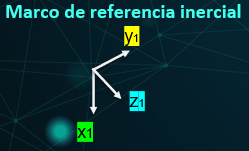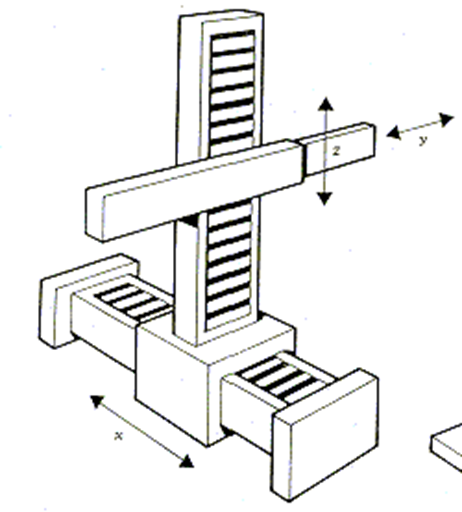

disp('Velocidad angular obtenida mediante el Jacobiano angular');

Velocidad angular obtenida mediante el Jacobiano angular


W=simplify (Jw_a*Qp');
pretty(W);

/ 0 \
|   |
| 0 |
|   |
\ 0 /



La velocidad angular resultante se explica en el hecho de que se trata de un robot de 3GDL de juntas prismáticas, por lo que no hay velocidad de rotación en ninguno de los ejes.